# KPIS ANALYSIS

clc
clear
close all
load('advanced_control_KPIS.mat');

## Voltage Unbalance and Quality analysis

Calculation of VUF and VD stats

scenarios = {'ev20','ev30','ev40'};

for i=1:numel(scenarios)
    scenario = scenarios{i};
    VUF_cntrl.(scenario) = abs(VUF_cntrl.(scenario));
    statsVUF_cntrl.(scenario).mean   = mean(VUF_cntrl.(scenario),3);
    statsVUF_cntrl.(scenario).median = median(VUF_cntrl.(scenario),3);
    statsVUF_cntrl.(scenario).std    = std(VUF_cntrl.(scenario),0,3);
    statsVUF_cntrl.(scenario).P95    = prctile(VUF_cntrl.(scenario),95,3);

    statsVD_cntrl.(scenario).mean   = mean(VD_cntrl.(scenario), 3);
    statsVD_cntrl.(scenario).median = median(VD_cntrl.(scenario), 3);
    statsVD_cntrl.(scenario).std    = std(VD_cntrl.(scenario), 0, 3);
    statsVD_cntrl.(scenario).P95    = prctile(VD_cntrl.(scenario), 95, 3);

    % grab the arrays: [T × B × N_MC]
    VUF_arr = VUF_cntrl.(scenario);
    VD_arr  = VD_cntrl.(scenario);
    [T, B, N_MC] = size(VUF_arr);
    
    % initialize top5 containers
    statsVUF_cntrl.(scenario).top5      = cell(T, B);
    statsVUF_cntrl.(scenario).top5Mean  = zeros(T, B);
    statsVD_cntrl.(scenario).top5       = cell(T, B);
    statsVD_cntrl.(scenario).top5Mean   = zeros(T, B);
    statsVUF_cntrl.(scenario).top5Idx = cell(T, B);  % indices of top5 runs
    statsVD_cntrl.(scenario).top5Idx  = cell(T, B);
    
    % make sure you already have P95 in statsVUF.(scenario).P95, etc.
    for t = 1:T
        for b = 1:B
            % extract the MC samples for this t,b
            vuf_vals = squeeze( VUF_arr(t,b,:) );
            vd_vals  = squeeze( VD_arr(t,b,:) );
            
            % get the precomputed 95th‐percentile
            vuf_cut = statsVUF_cntrl.(scenario).P95(t,b);
            vd_cut  = statsVD_cntrl.(scenario).P95(t,b);
            
            % find the "top 5%" samples
            vuf_top5 = vuf_vals( vuf_vals > vuf_cut );
            vd_top5  = vd_vals(  vd_vals  > vd_cut  );
            
            % store them
            statsVUF_cntrl.(scenario).top5{t,b}     = vuf_top5;
            statsVUF_cntrl.(scenario).top5Mean(t,b) = mean(vuf_top5);
            
            statsVD_cntrl.(scenario).top5{t,b}      = vd_top5;
            statsVD_cntrl.(scenario).top5Mean(t,b)  = mean(vd_top5);
        end
    end
end
save('advanced_control_KPIS.mat', 'VUF_cntrl', '-append');
save('statsVoltage_cntrl_advanced.mat', 'statsVUF_cntrl', 'statsVD_cntrl');


## VUF during late-night early-morning hours across all buses

VD at the same script just changing the metrics and limits

clear
load('statsVoltage_cntrl_advanced.mat');

scenarios = {'ev20','ev30','ev40'};
colors = lines(numel(scenarios));

% === Select peak hours (17:00–23:00) ===
% Your timestep resolution is 15min -> 4 steps/hour
% 17:00 = step 68, 23:00 = step 92
time_indices = 4:28;    

figure; hold on;

for i = 1:numel(scenarios)
    s = scenarios{i};

    % Mean across peak hours (average over timesteps 4:28)
    mean_over_buses = mean(statsVD_cntrl.(s).mean(time_indices,2:37),1);  % 1×36
    p95_over_buses  = mean(statsVD_cntrl.(s).P95(time_indices,2:37),1);   % 1×36

    % Plot mean (solid) and P95 (dashed)
    plot(2:37, mean_over_buses, '-', 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', [s ' mean']);
    plot(2:37, p95_over_buses, '--', 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', [s ' P95']);
end

xlabel('Bus number (2–37)');
ylabel('VD [%]');
title('VD Mean and P95 across buses (17:00–23:00)');
yline(10,'--k','Limit 2%', 'DisplayName', 'VD limit');
grid on; legend('Location','northwest');

## General boxplot for Grid VUF and VD distribution

General observation : the last 12 nodes are the most valnurable (as expected) in the grid with bus 36 behaving the worst of all.

% BUS 36 :

- VUF_p95 : 1.787 , VUF_top5 = 1.981

- VD_p95 : 7.18 , VD_top5 = 7.77

We need to make further investigation during the time intervals, specially on peak-demand hours

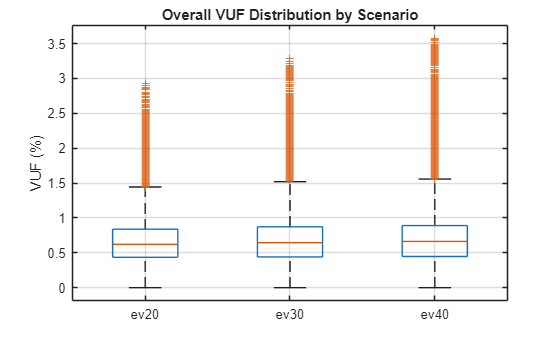

clear
load('advanced_control_KPIS.mat');
scenarios = {'ev20','ev30','ev40'};
B = size(VUF_cntrl.ev20,2);

%% 1) Boxplots of overall VUF & VD distributions
% flatten into [all_samples × 1] per scenario
allVUF = cell(1,numel(scenarios));
allVD  = cell(1,numel(scenarios));
for i = 1:numel(scenarios)
    s = scenarios{i};
    arr = VUF_cntrl.(s);           % [T×B×N_MC]
    allVUF{i} = arr(:);      % vectorize
    arr = VD_cntrl.(s);
    allVD{i}  = arr(:);
end

figure('Name','VUF Distributions','NumberTitle','off');
boxplot(vertcat(allVUF{:}), ...
        repelem(scenarios, cellfun(@numel,allVUF)), ...
        'LabelVerbosity','minor');
ylabel('VUF (%)');
title('Overall VUF Distribution by Scenario');
grid on;

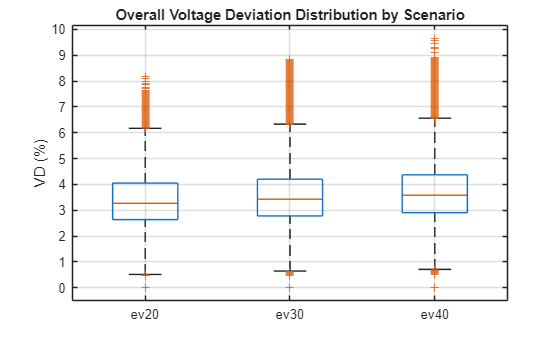


figure('Name','VD Distributions','NumberTitle','off');
boxplot(vertcat(allVD{:}), ...
        repelem(scenarios, cellfun(@numel,allVD)), ...
        'LabelVerbosity','minor');
ylabel('VD (%)');
title('Overall Voltage Deviation Distribution by Scenario');
grid on;

## summary table of min,mean, max VUF and VD

clear
load('statsVoltage.mat');
% Specify the three buses you want to analyze
nodeList  = [34, 35, 36];    % replace with your bus indices
scenarios = {'base','ev10','ev30','ev50'};

for i = 1:numel(scenarios)
    s = scenarios{i};
    fprintf('--- Scenario: %s ---\n', s);
    
    for b = nodeList
        % Extract the 24 h (or 96 step) series for this bus
        vuf_p95   = statsVUF_cntrl.(s).P95(:,b);
        vuf_top5  = statsVUF_cntrl.(s).top5Mean(:,b);
        vd_p95    = statsVD_cntrl.(s).P95(:,b);
        vd_top5   = statsVD_cntrl.(s).top5Mean(:,b);
        
        % Compute min, mean, max
        vuf_p95_stats  = [min(vuf_p95),  mean(vuf_p95),  max(vuf_p95)];
        vuf_top5_stats = [min(vuf_top5), mean(vuf_top5), max(vuf_top5)];
        vd_p95_stats   = [min(vd_p95),   mean(vd_p95),   max(vd_p95)];
        vd_top5_stats  = [min(vd_top5),  mean(vd_top5),  max(vd_top5)];
        
        % Print results
        fprintf(' Bus %2d:\n', b);
        fprintf('  VUF  P95    → min: %6.2f%%, mean: %6.2f%%, max: %6.2f%%\n', vuf_p95_stats);
        fprintf('  VUF  Top 5%% → min: %6.2f%%, mean: %6.2f%%, max: %6.2f%%\n', vuf_top5_stats);
        fprintf('  VD   P95    → min: %6.2f%%, mean: %6.2f%%, max: %6.2f%%\n', vd_p95_stats);
        fprintf('  VD   Top 5%% → min: %6.2f%%, mean: %6.2f%%, max: %6.2f%%\n\n', vd_top5_stats);
    end
end

## MORNING - EVENING RISK OF VUF VIOLATION

This shows the observed frequency of violations.

%% Probability metrics of VUF violations — Evening
%% Probability & Severity of VUF violations — Evening window + Smag (+ AOT)
clear
load('advanced_control_KPIS.mat','VUF_cntrl');           % VUF.(scenario): [96 x B x MC]
scenarios  = {'ev20','ev30','ev40'};
VUF_limit  = 2;                      % in same units as VUF (2% if VUF in %)

% ---- Window indices (15-min resolution; 96 steps/day) ----
toIdx      = @(hrs) sort(cell2mat(arrayfun(@(h) (h-1)*4 + (1:4), hrs, 'UniformOutput', false)));
idxEvening = toIdx(1:7);           % 17:00–23:00 inclusive  (your choice)
step_min   = 15;

% ---- Sizes ----
[~,B,MC] = size(VUF_cntrl.(scenarios{1}));
S  = numel(scenarios);
Te = numel(idxEvening);

% ---- Outputs (per bus & scenario) ----
Pany_bus   = zeros(B,S);    % %
Stime_bus  = nan(B,S);     % % (conditional duration)
RoV_bus    = zeros(B,S);    % %
Smag_bus   = nan(B,S);     % % of the limit (average magnitude when violating)

for si = 1:S
    s  = scenarios{si};
    V  = VUF_cntrl.(s);                             % [96 x B x MC]
    Ve = V(idxEvening,:,:);                   % [Te x B x MC]

    % --- Binary violation (time-based) ---
    viol   = Ve > VUF_limit;                  % logical
    any_t  = squeeze(any(viol,1));            % [B x MC]
    Pany_bus(:,si)  = mean(any_t, 2) * 100;   % %
    frac   = squeeze(sum(viol,1)) / Te;       % [B x MC]
    num_viol_runs   = sum(any_t, 2);          % [B x 1]
    Stime_bus(:,si) = (sum(frac .* any_t, 2) ./ max(num_viol_runs,1)) * 100;
    Stime_bus(num_viol_runs==0, si) = NaN;
    RoV_bus(:,si)   = squeeze(sum(viol, [1 3]) ./ (Te*MC)) * 100; % %

    % --- Magnitude-based (relative exceedance) ---
    % e = (V - limit)_+ / limit  → unitless, "fraction of the limit"
    E = max(Ve - VUF_limit, 0) ./ VUF_limit;  % [Te x B x MC]
    I = E > 0;                                 % same as 'viol' logically

    sumE = squeeze(sum(E, [1 3]));            % [B x 1] total relative excess over all (t,run)
    sumI = squeeze(sum(I, [1 3]));            % [B x 1] total violating minutes over all (t,run)

    % Minute-weighted magnitude severity (as % of the limit for reporting)
    Sm = (sumE ./ max(sumI,1)) * 100;         % % of the limit
    Sm(sumI==0) = NaN;                        % undefined if no violations
    Smag_bus(:,si) = Sm;
end

% ---- Sanity checks ----
% 1) RoV ≈ P(any) * Stime / 100  (both in %)
%check_RoV = max(abs(RoV_bus - (Pany_bus .* Stime_bus / 100)), [], 'all', 'omitnan');
%fprintf('Max |RoV - P(any)*Stime/100| = %.3g (%%)\n', check_RoV);

% convert Stime to minutes per violating run ----
ExpMin_bus = Stime_bus/100 * (Te*step_min);   % [B x S]

% ---- Store results ----
probVUF_cntrl.bus = struct( ...
    'Pany',        Pany_bus, ...       
    'Stime',    Stime_bus, ...      (conditional)
    'RoV',         RoV_bus, ...         
    'Smag',        Smag_bus, ...       (avg excess when violating)
    'ExpMin',      ExpMin_bus);      % [B x S] minutes

save('VUFprob_cntrl_advanced.mat', 'probVUF_cntrl');

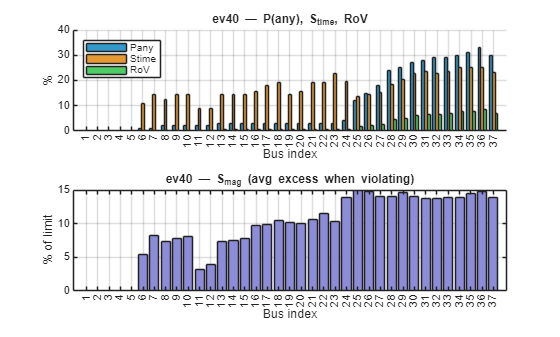


% === Bus-level comparison plots: Evening ===
scenarios = {'ev20','ev30','ev40'};
si = 3;                              % pick scenario index
figure;
tiledlayout(2,1,"TileSpacing","compact");

bus_ids = 1:B;   % x-axis: bus numbers

% ---- (1) Pany / Stime / RoV (all in %) ----
nexttile;
hold on;
bar(bus_ids - 0.25, Pany_bus(:,si), 0.25, 'FaceColor',[0.2 0.6 0.8]); 
bar(bus_ids,          Stime_bus(:,si), 0.25, 'FaceColor',[0.9 0.6 0.2]); 
bar(bus_ids + 0.25,   RoV_bus(:,si),   0.25, 'FaceColor',[0.3 0.8 0.4]);
hold off;
xticks(bus_ids);
xlabel('Bus index');
ylabel('%');
title(sprintf('%s — P(any), S_{time}, RoV', scenarios{si}));
legend({'Pany','Stime','RoV'}, 'Location','northwest');
grid on;

% ---- (2) Smag (avg excess when violating) ----
nexttile;
% If Smag_bus is stored as fraction, convert with "*100" before plotting.
bar(bus_ids, Smag_bus(:,si), 'FaceColor',[0.55 0.55 0.85]);
xticks(bus_ids);
xlabel('Bus index');
ylabel('% of limit');                      % Smag is "percent of the limit"
title(sprintf('%s — S_{mag} (avg excess when violating)', scenarios{si}));
grid on;

## SAME FOR VD

%% Probability & Severity of VD violations — Evening window + Smag
clear
load('advanced_control_KPIS.mat','VD_cntrl');            % VD.(scenario): [96 x B x MC] (can be signed)
scenarios  = {'ev20','ev30','ev40'};
VD_limit   = 10;                     

% ---- Window indices (15-min resolution; 96 steps/day) ----
toIdx      = @(hrs) sort(cell2mat(arrayfun(@(h) (h-1)*4 + (1:4), hrs, 'UniformOutput', false)));
idxEvening = toIdx(1:7);           % 17:00–23:00 inclusive
step_min   = 15;

% ---- Sizes ----
[~,B,MC] = size(VD_cntrl.(scenarios{1}));
S  = numel(scenarios);
Te = numel(idxEvening);

% ---- Outputs (per bus & scenario) ----
Pany_bus   = zeros(B,S);    % %
Stime_bus  = nan(B,S);      % % (conditional duration)
RoV_bus    = zeros(B,S);    % %
Smag_bus   = nan(B,S);      % % of the limit (avg magnitude when violating)

for si = 1:S
    s  = scenarios{si};
    V  = abs(VD_cntrl.(s));                       % use absolute VD against the limit
    Ve = V(idxEvening,:,:);                 % [Te x B x MC]

    % --- Binary violation (time-based) ---
    viol   = Ve >= VD_limit;                 % logical
    any_t  = squeeze(any(viol,1));          % [B x MC]
    Pany_bus(:,si)  = mean(any_t, 2) * 100; % %
    frac   = squeeze(sum(viol,1)) / Te;     % [B x MC]
    num_viol_runs   = sum(any_t, 2);        % [B x 1]
    Stime_bus(:,si) = (sum(frac .* any_t, 2) ./ max(num_viol_runs,1)) * 100;
    Stime_bus(num_viol_runs==0, si) = NaN;
    RoV_bus(:,si)   = squeeze(sum(viol, [1 3]) ./ (Te*MC)) * 100; % %

    % --- Magnitude-based (relative exceedance) ---
    % e = (|VD| - limit)_+ / limit  → unitless, "fraction of the limit"
    E = max(Ve - VD_limit, 0) ./ VD_limit;  % [Te x B x MC]
    I = E > 0;

    sumE = squeeze(sum(E, [1 3]));          % [B x 1] total relative excess (t,run)
    sumI = squeeze(sum(I, [1 3]));          % [B x 1] total violating minutes (t,run)

    % Minute-weighted magnitude severity (report as % of the limit)
    Sm = (sumE ./ max(sumI,1)) * 100;       % %
    Sm(sumI==0) = NaN;
    Smag_bus(:,si) = Sm;
end

% ---- Convert Stime to minutes per violating run ----
ExpMin_bus = Stime_bus/100 * (Te*step_min);   % [B x S]

% ---- Store results ----
probVD_cntrl.bus = struct( ...
    'Pany',   Pany_bus, ...        % [B x S] %
    'Stime',  Stime_bus, ...       % [B x S] % (conditional)
    'RoV',    RoV_bus, ...         % [B x S] %
    'Smag',   Smag_bus, ...        % [B x S] % of limit (avg excess when violating)
    'ExpMin', ExpMin_bus );        % [B x S] minutes

% === Bus-level comparison plots: Evening ===
scenarios = {'ev20','ev30','ev40'};
si = 3;                              % pick scenario index
figure;
tiledlayout(2,1,"TileSpacing","compact");

bus_ids = 1:B;   % x-axis: bus numbers

% ---- (1) Pany / Stime / RoV (all in %) ----
nexttile;
hold on;
bar(bus_ids - 0.25, Pany_bus(:,si), 0.25, 'FaceColor',[0.2 0.6 0.8]); 
bar(bus_ids,          Stime_bus(:,si), 0.25, 'FaceColor',[0.9 0.6 0.2]); 
bar(bus_ids + 0.25,   RoV_bus(:,si),   0.25, 'FaceColor',[0.3 0.8 0.4]);
hold off;
xticks(bus_ids);
xlabel('Bus index');
ylabel('%');
title(sprintf('%s — Pany, Stime, RoV', scenarios{si}));
legend({'Pany','Stime','RoV'}, 'Location','northwest');
grid on;

% ---- (2) Smag (avg excess when violating) ----
nexttile;
% If Smag_bus is stored as fraction, convert with "*100" before plotting.
bar(bus_ids, Smag_bus(:,si), 'FaceColor',[0.55 0.55 0.85]);
xticks(bus_ids);
xlabel('Bus index');
ylabel('% of limit');                      % Smag is "percent of the limit"
title(sprintf('%s — Smag', scenarios{si}));
grid on;

## Now we plot the VUF, VD, VAN, VBN, VCN for Bus 36

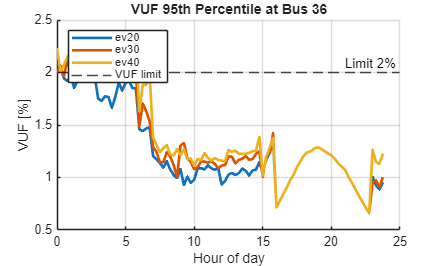

clear
load('statsVoltage_cntrl_advanced.mat');
scenarios = {'ev20','ev30','ev40'};

colors = lines(numel(scenarios));
time = (0:95) * 0.25;   % 96 steps, 15min each → hours

figure; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    % Extract 95th percentile for bus 36 (timesteps × buses)
    vuf_p95 = statsVUF_cntrl.(s).P95(:,36);
    plot(time, vuf_p95, 'LineWidth', 2, 'Color', colors(i,:), 'DisplayName', s);
end
yline(2,'--k','Limit 2%', 'DisplayName', 'VUF limit');
xlabel('Hour of day'); ylabel('VUF [%]');
title('VUF 95th Percentile at Bus 36');
grid on; legend('Location','northwest');

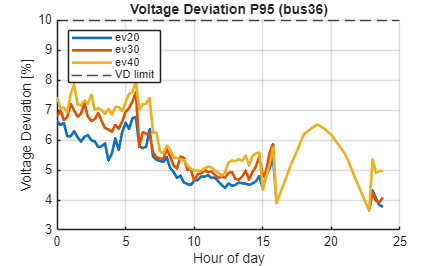


% VD
figure; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    vd_p95 = statsVD_cntrl.(s).P95;  % [96 × buses]
    % Take global average across buses for simplicity
    vd_p95_all = vd_p95(:,36); 
    plot(time, vd_p95_all, 'LineWidth', 2, 'Color', colors(i,:), 'DisplayName', s);
end
yline(10,'--k','Limit 10%','DisplayName','VD limit');
xlabel('Hour of day'); ylabel('Voltage Deviation [%]');
title('Voltage Deviation P95 (bus36)');
grid on; legend('Location','northwest');

clear
load('simple_control_KPIS.mat','Volt_cntrl');  

% --- Settings ---
scenarios   = {'ev20','ev30','ev40'}; 
bus_id      = 36;
time_hours  = (0:95) * 0.25;                  % 96 steps, 15 min each
pct_lowtail = 5;                               % 5th percentile (low tail)
phase_colors = [0.85 0.33 0.10; 0.00 0.45 0.74; 0.47 0.67 0.19]; % VAN,VBN,VCN colors
phase_labels = {'VAN','VBN','VCN'};

figure('Name',sprintf('Phase Voltages – Bus %d – %dth percentile',bus_id,pct_lowtail),...
       'Color','w','Position',[100 100 900 800]);

for i = 1:numel(scenarios)
    s = scenarios{i};
    subplot(numel(scenarios),1,i); hold on;

    % Extract all MC runs for this bus (96 x MC)
    VAN_all = squeeze(Volt_cntrl.(s).VAN(:,bus_id,:));
    VBN_all = squeeze(Volt_cntrl.(s).VBN(:,bus_id,:));
    VCN_all = squeeze(Volt_cntrl.(s).VCN(:,bus_id,:));

    % Low-tail percentile across MC runs at each timestep
    VAN_p = prctile(VAN_all, pct_lowtail, 2);
    VBN_p = prctile(VBN_all, pct_lowtail, 2);
    VCN_p = prctile(VCN_all, pct_lowtail, 2);

    % Plot
    plot(time_hours, VAN_p, 'LineWidth',2, 'Color',phase_colors(1,:), 'DisplayName',phase_labels{1});
    plot(time_hours, VBN_p, 'LineWidth',2, 'Color',phase_colors(2,:), 'DisplayName',phase_labels{2});
    plot(time_hours, VCN_p, 'LineWidth',2, 'Color',phase_colors(3,:), 'DisplayName',phase_labels{3});

    grid on; xlim([0 23.75]);
    xlabel('Hour of day'); ylabel('Voltage');   % units: V or pu depending on your data
    title(sprintf('%s – Bus %d – %dth percentile across MC', s, bus_id, pct_lowtail));
    legend('Location','best');
end

sgtitle(sprintf('Low-tail (P%d) Phase Voltages at Bus %d', pct_lowtail, bus_id));